clearvars
close all
clc
N = 8; % N of steps
z0 = 5; % height of camera
gamma = 0.1; % uniform noise coefficient

## Generate spherical beacon

% azi_res = 7; % azimutal angle resolution
% elev_res = 7; % elevation angle resolution
% azis = -pi : 2*pi / (azi_res - 1) : pi;
% elevs = -pi : 2*pi / (elev_res - 1) : pi;
% center = [25; 25; 6]; % center of sphere
% radius = 3; % radius of sphere
% points = [];
% 
% figure
% scatter3(center(1), center(2), center(3), 'Marker', '*', 'HandleVisibility','off');
% hold on
% 
% for elev = 1:elev_res
%     [x, y ,z] = sph2cart(azis, elevs(elev), radius * ones(1, azi_res));
%     curr_elev = [x; y; z] + center;
%     plot3(curr_elev(1,:), curr_elev(2, :), curr_elev(3,:), "LineStyle","--", "LineWidth", 0.1, "Color", "k", 'HandleVisibility','off');
%     points = [points curr_elev];
% end
% 
% n_points = length(points);
% 
% for j = 1:azi_res*elev_res
%     scatter3(points(1,j) , points(2,j) , points(3,j) , 'Marker' , '.', 'HandleVisibility','off', "MarkerEdgeColor", "g");
% end
% title("View of " + n_points + " points spherical beacon")
% axis equal

## Generate cuboid beacon

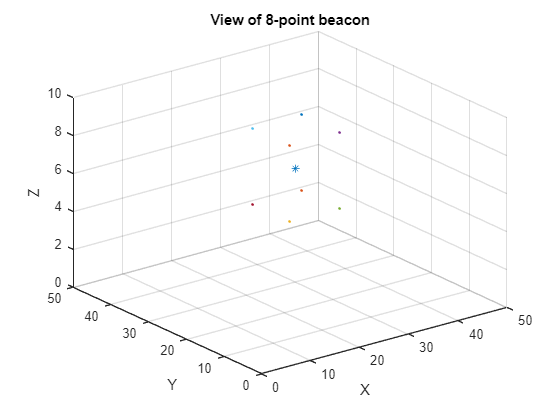

n_points = 8;
points = [25 25 35 35 25 25 35 35; 25 25 25 25 35 35 35 35; 8 4 8 4 8 4 8 4];
center = mean(points, 2);
add_point = center + [3; 3; 0];
figure
scatter3(center(1), center(2), center(3), 'Marker', '*', 'HandleVisibility','off');
hold on
%scatter3(add_point(1), add_point(2), add_point(3), 'Marker', '*', 'HandleVisibility','off');
for  j = 1:n_points
    scatter3(points(1,j) , points(2,j) , points(3,j) , 'Marker' , '.', 'HandleVisibility','off');
    hold on;
end
title("View of " + n_points + "-point beacon")
xlim([0 50])
ylim([0 50])
zlim([0 10])
xlabel 'X'
ylabel 'Y'
zlabel 'Z'

## Calculate trajectory

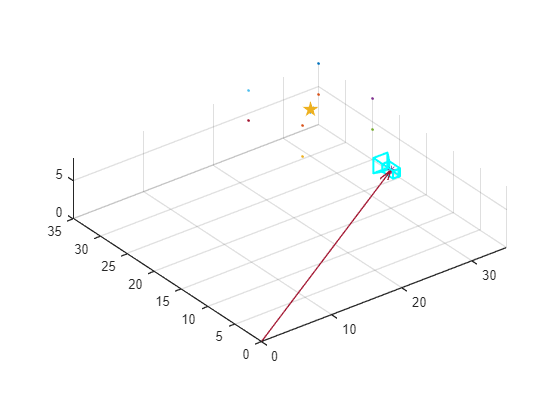

figure
scatter3(center(1), center(2), center(3), 'Marker', '*', 'HandleVisibility','off');
hold on
%scatter3(add_point(1), add_point(2), add_point(3), 'Marker', '*', 'HandleVisibility','off');
for  j = 1:n_points
    scatter3(points(1,j) , points(2,j) , points(3,j) , 'Marker' , '.', 'HandleVisibility','off');
    hold on;
end
axis equal
scatter3(center(1), center(2), center(3), 'Marker' , 'p', "LineWidth", 2, "DisplayName", "Center of camera rotation");
points_3D = [points; ones(1,n_points)]; % normalize

f = 1; % focal length
r0 = 15; % radius of trajectory
x0 = center(1);
y0 = center(2) - r0;
Rwb = [1 0 0; 0 0 1;0 -1 0]; % Initial pose of camera (body 2 word)
Rbw = Rwb'; % Initial pose of camera (word 2 body)
Twb = [x0;y0;z0]; % Initial position of camera
Tbw = -Twb;
alpha = 2 * pi / N; % angle of rotation from each view
currR = Rbw; % save initial absolute orientation
currT = Twb; % save initial absolute position
rotation = [cos(alpha) -sin(alpha) 0; sin(alpha) cos(alpha) 0; 0 0 1]; % relative rotation between each view
pose = rigid3d(currR,currT');

scatter3(currT(1), currT(2), currT(3), 'Marker',"*", 'HandleVisibility','off')
plotCamera('AbsolutePose',pose,'Size', 1, 'Opacity',0,"Color","cyan", "Label", "1");
quiver3(0, 0, 0, currT(1), currT(2), currT(3), "AutoscaleFactor", 1,  'HandleVisibility','off');

%% Generate history matrices and save the first pose
T_history_abs = zeros(3, 1, N);
R_history_abs = zeros(3, 3, N);
R_history_abs(:, :, 1) = currR;
T_history_abs(:, :, 1) = currT;


## Generate the whole history of poses (R and T)

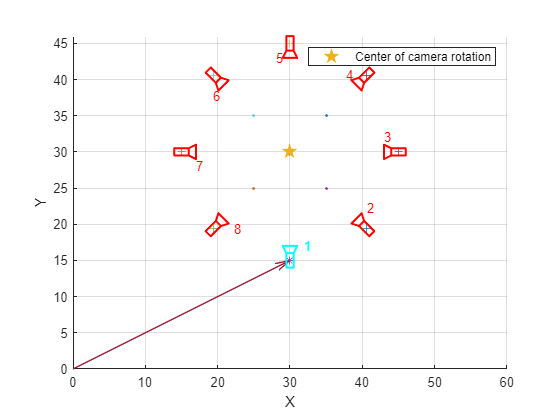

for i = 1 : N - 1
    currR = currR*rotation';
    currT = Twb + [r0 * sin(alpha * i); r0 * (1 -cos(alpha * i)); 0];
    pose = rigid3d(currR,currT');
    scatter3(currT(1), currT(2), currT(3), 'Marker',"+",'HandleVisibility','off')
    plotCamera('AbsolutePose',pose,'Size',1, 'Opacity',0, "Label", "" + (i + 1));
    T_history_abs(:, :, i + 1) = currT;
    R_history_abs(:, :, i + 1) = currR;
end

xlabel 'X'
ylabel 'Y'
zlabel 'Z'
view([0 90])
xlim([0 60])
axis equal
legend

## Now computing E matrices from R and T

E_history = cell(1,N); % create a cell array equal to the number of poses
EN_history = cell(1,N);
correct_angles = cell(N,N);
for i = 1:N
    Es = zeros(3,3,N);
    for j = 1:N
        if j == i
            R_ij = eye(3);
        elseif j > i 
            R_ij = rotation'^(j - i);
        else
            R_ij = rotation'^(N + j - i);
        end
        angle = rotm2eul(R_ij);
        angle = angle(1);
        if abs(angle) < 1e-3
            correct_angles(i,j) = {'X'};
        else
            correct_angles(i,j) = {angle * 180 / pi};
        end
        T_ij = T_history_abs(:, j) - T_history_abs(:, i);
        E = getSkew(T_ij) * R_ij;
        Es(:, :, j) = E;
    end
    E_history(i) = {Es}; % save ideal E matrix
    EN_history(i) = {Es + gamma*rand(3, 3)}; % poison E matrix with noise to simulate reconstruction error
end
correct_angles

correct_angles = 8×8 cell array
    {'X'        }    {[      -45]}    {[ -90.0000]}    {[     -135]}    {[-180.0000]}    {[ 135.0000]}    {[  90.0000]}    {[  45.0000]}
    {[  45.0000]}    {'X'        }    {[      -45]}    {[ -90.0000]}    {[     -135]}    {[-180.0000]}    {[ 135.0000]}    {[  90.0000]}
    {[  90.0000]}    {[  45.0000]}    {'X'        }    {[      -45]}    {[ -90.0000]}    {[     -135]}    {[-180.0000]}    {[ 135.0000]}
    {[ 135.0000]}    {[  90.0000]}    {[  45.0000]}    {'X'        }    {[      -45]}    {[ -90.0000]}    {[     -135]}    {[-180.0000]}
    {[-180.0000]}    {[ 135.0000]}    {[  90.0000]}    {[  45.0000]}    {'X'        }    {[      -45]}    {[ -90.0000]}    {[     -135]}
    {[     -135]}    {[-180.0000]}    {[ 135.0000]}    {[  90.0000]}    {[  45.0000]}    {'X'        }    {[      -45]}    {[ -90.0000]}
    {[ -90.0000]}    {[     -135]}    {[-180.0000]}    {[ 135.0000]}    {[  90.0000]}    {[  45.0000]}    {'X'        }    {[      -45]}
    {[   

## Retrieve R and T from noisy E

R1_rel = cell(N, N);
T1_rel = cell(N, N);
R2_rel = cell(N, N);
T2_rel = cell(N, N);

for i = 1:N
    for j = 1:N
        %% Compute R_ij and T_ij
        E = E_history{i}(:,:,j); % Extract E_ij
        %E = EN_history{i}(:,:,j); % Uncomment to to use noisy
        [U, S, V] = svd(E); % Singular value decomp
        % Safeguard against non SO(3) matrix
        if (det(U)<0)
            U = [U(:,1) U(:,2) -U(:,3)];
        end
        if (det(V)<0)
            V = [V(:,1) V(:,2) -V(:,3)]; 
        end
        sigmas = diag(S); % Get singular values
        avg = (sigmas(1) + sigmas(2)) / 2; % Average values
        sigmas = [avg; avg; 0]; % Substitute
        S = diag(sigmas);
        Rp = [cos(pi/2) -sin(pi/2) 0; sin(pi/2) cos(pi/2) 0; 0 0 1]; % Rotation of pi/2 around z axis
        Rm = [cos(-pi/2) -sin(-pi/2) 0; sin(-pi/2) cos(-pi/2) 0; 0 0 1]; % Rotation of -pi/2 around z axis
        skewT1 = U * Rp * S * U'; % Get T matrix
        currT1 = getT(skewT1); % Get T from T matrix
        currT2 = -getT(skewT1);
        currR1 = U * Rp' * V'; % Get R matrix
        currR2 = U * Rm' * V';
        R1_rel(i,j) = {currR1}; % Save data
        T1_rel(i,j) = {currT1};
        R2_rel(i,j) = {currR2};
        T2_rel(i,j) = {currT2};
    end
end

## Project points to evaluate correct combination

This part was also computed using absolute orientation and not relative, results were the same and T estimation could not be completed as well.

R_rel = cell(N,N);
T_rel = cell(N,N);
votes = zeros(N,N);
% Case R1, T1
for i = 1:N
    for j = 1:N
        g = [R1_rel{i,j}', -R1_rel{i,j}'*T1_rel{i,j}; 0 0 0 1];
        cam_coord = g * [center; 1];
        if cam_coord(3) > 0 % if z coordinate is positive for relative rotated view
            votes(i, j) = votes(i, j) + 1;
            R_rel(i, j) = R1_rel(i,j);
            T_rel(i, j) = T1_rel(i,j);
        end
    end
end

% Case R1, T2
for i = 1:N
    for j = 1:N
        g = [R1_rel{i,j}', -R1_rel{i,j}'*T2_rel{i,j}; 0 0 0 1];
        cam_coord = g * [center; 1];
        if cam_coord(3) > 0
            votes(i, j) = votes(i, j) + 1;
            R_rel(i, j) = R1_rel(i,j);
            T_rel(i, j) = T2_rel(i,j);
        end
    end
end

% Case R2, T1
for i = 1:N
    for j = 1:N
        g = [R2_rel{i,j}', -R2_rel{i,j}'*T1_rel{i,j}; 0 0 0 1];
        cam_coord = g * [center; 1];
        if cam_coord(3) > 0
            votes(i, j) = votes(i, j) + 1;
            R_rel(i, j) = R2_rel(i,j);
            T_rel(i, j) = T1_rel(i,j);
        end
    end
end

% Case R2, T2
for i = 1:N
    for j = 1:N
        g = [R2_rel{i,j}', -R2_rel{i,j}'*T2_rel{i,j}; 0 0 0 1];
        cam_coord = g * [center; 1];
        if cam_coord(3) > 0
            votes(i, j) = votes(i, j) + 1;
            R_rel(i, j) = R2_rel(i,j);
            T_rel(i, j) = T2_rel(i,j);
        end
    end
end

votes

votes =      4     2     2     2     2     2     2     2
     2     4     2     2     2     2     2     2
     2     2     4     2     2     2     2     2
     2     2     2     4     2     2     2     2
     2     2     2     2     4     2     2     2
     2     2     2     2     2     4     2     2
     2     2     2     2     2     2     4     2
     2     2     2     2     2     2     2     4


In ideal conditions, each non-diagonal cell should have 1 vote (that is, only one T-R valid combination).

In this case we observe 2 since we are using the z-axis orientation as condition, which does not solve the twisted pair problem.

## Check trajectory

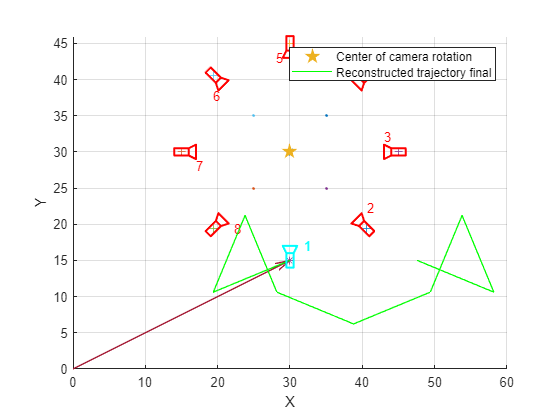

currP = Twb;
traj = [Twb];
for i = 1:N
    nextP = currP + T_rel{i, 1 + mod(i, N)};
    traj = [traj nextP];
    currP = nextP;
end
plot3(traj(1, :), traj(2, :), traj(3, :), "DisplayName", "Reconstructed trajectory final", "Color", "g")
view([0 90])

## Check angles

est_rel_angles = cell(N, N);

for i = 1:N
    for j = 1:N
        currR = R_rel{i, j};
        if ~isempty(currR) && i ~= j
            angle = rotm2eul(currR);
            angle = angle(1);
            if abs(angle) < 1e-3; angle = 0; end
            est_rel_angles(i, j)  = {angle * 180 / pi};
        else
            est_rel_angles(i, j) = {'X'};
        end
    end
end

correct_angles

correct_angles = 8×8 cell array
    {'X'        }    {[      -45]}    {[ -90.0000]}    {[     -135]}    {[-180.0000]}    {[ 135.0000]}    {[  90.0000]}    {[  45.0000]}
    {[  45.0000]}    {'X'        }    {[      -45]}    {[ -90.0000]}    {[     -135]}    {[-180.0000]}    {[ 135.0000]}    {[  90.0000]}
    {[  90.0000]}    {[  45.0000]}    {'X'        }    {[      -45]}    {[ -90.0000]}    {[     -135]}    {[-180.0000]}    {[ 135.0000]}
    {[ 135.0000]}    {[  90.0000]}    {[  45.0000]}    {'X'        }    {[      -45]}    {[ -90.0000]}    {[     -135]}    {[-180.0000]}
    {[-180.0000]}    {[ 135.0000]}    {[  90.0000]}    {[  45.0000]}    {'X'        }    {[      -45]}    {[ -90.0000]}    {[     -135]}
    {[     -135]}    {[-180.0000]}    {[ 135.0000]}    {[  90.0000]}    {[  45.0000]}    {'X'        }    {[      -45]}    {[ -90.0000]}
    {[ -90.0000]}    {[     -135]}    {[-180.0000]}    {[ 135.0000]}    {[  90.0000]}    {[  45.0000]}    {'X'        }    {[      -45]}
    {[   

est_rel_angles

est_rel_angles = 8×8 cell array
    {'X'        }    {[      -45]}    {[ -90.0000]}    {[     -135]}    {[-180.0000]}    {[ 135.0000]}    {[  90.0000]}    {[  45.0000]}
    {[  45.0000]}    {'X'        }    {[      -45]}    {[ -90.0000]}    {[     -135]}    {[-180.0000]}    {[ 135.0000]}    {[       90]}
    {[  90.0000]}    {[  45.0000]}    {'X'        }    {[      -45]}    {[ -90.0000]}    {[     -135]}    {[-180.0000]}    {[ 135.0000]}
    {[ 135.0000]}    {[  90.0000]}    {[  45.0000]}    {'X'        }    {[      -45]}    {[      -90]}    {[     -135]}    {[-180.0000]}
    {[-180.0000]}    {[ 135.0000]}    {[  90.0000]}    {[  45.0000]}    {'X'        }    {[      -45]}    {[ -90.0000]}    {[     -135]}
    {[     -135]}    {[-180.0000]}    {[ 135.0000]}    {[       90]}    {[  45.0000]}    {'X'        }    {[      -45]}    {[ -90.0000]}
    {[      -90]}    {[     -135]}    {[-180.0000]}    {[ 135.0000]}    {[  90.0000]}    {[  45.0000]}    {'X'        }    {[      -45]}
    {[ -4

## Projection of 3D points onto image plane w/ and w/out normalization

PI0 = [eye(3) zeros(3,1)]

PI0 =      1     0     0     0
     0     1     0     0
     0     0     1     0


K_f = eye(3)

K_f =      1     0     0
     0     1     0
     0     0     1


K_s = eye(3)

K_s =      1     0     0
     0     1     0
     0     0     1


K = K_s * K_f

K =      1     0     0
     0     1     0
     0     0     1


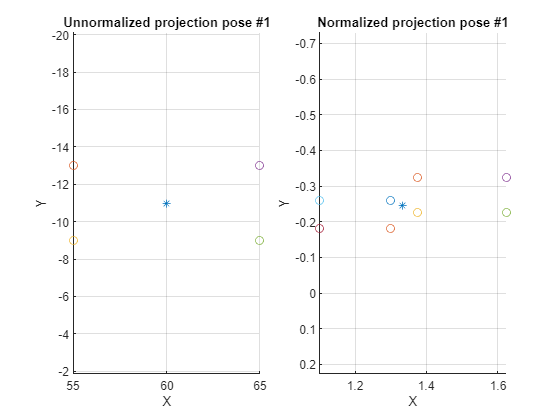

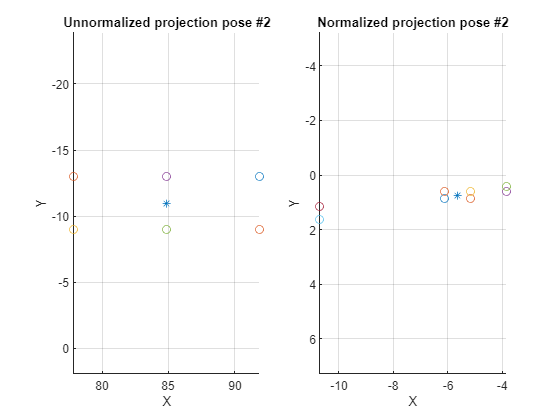

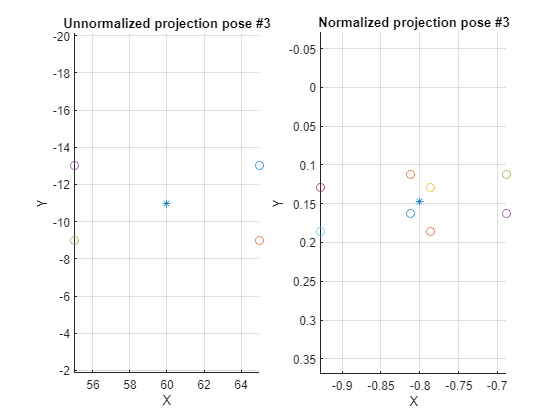

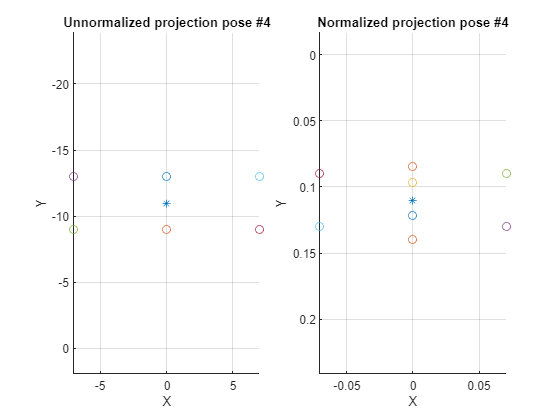

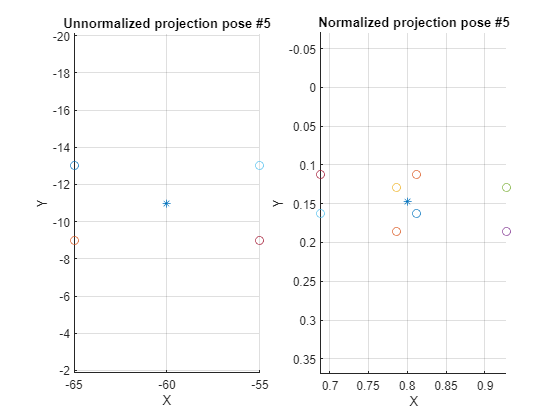

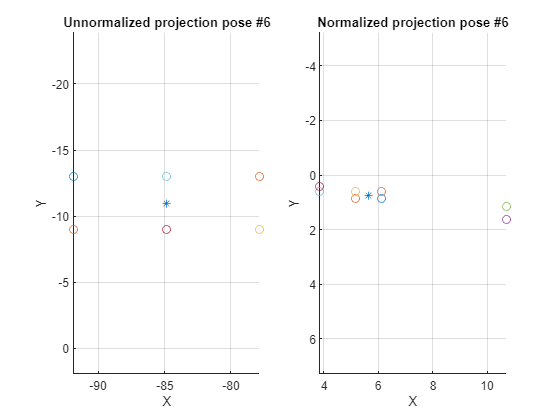

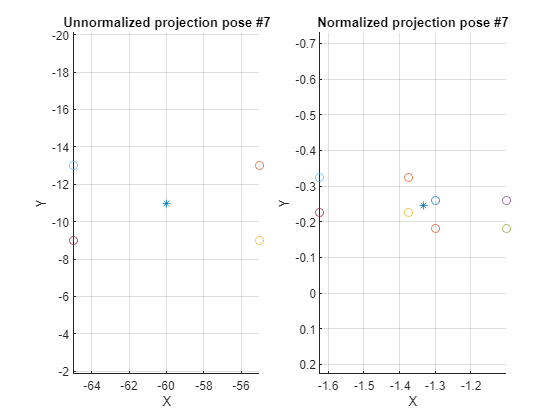

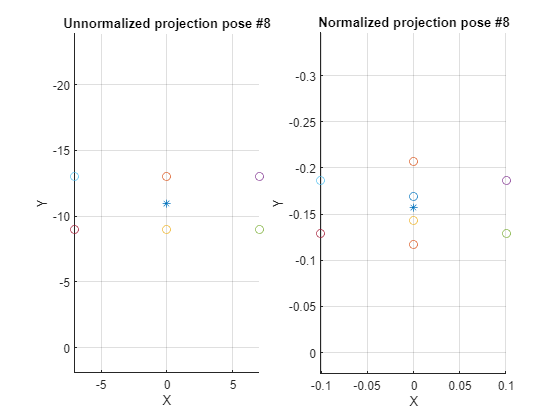

im_planes_og = cell(N, n_points);
im_planes_norm = cell(N, n_points);

for i = 1:N
    currR = R_history_abs(:, :, i);
    currT = T_history_abs(:, :, i);
    g = [currR currR*currT; 0 0 0 1];
    proj_c_og = K * PI0 * g * [center; 1];
    proj_c_norm = proj_c_og / proj_c_og(3);
    figure
    subplot(1,2,1)
    hold on
    scatter3(proj_c_og(1), proj_c_og(2), proj_c_og(3), "Marker", "*");
    subplot(1,2,2)
    hold on
    scatter3(proj_c_norm(1), proj_c_norm(2), proj_c_norm(3), "Marker", "*");
    for j = 1:n_points
        im_point = K * PI0 * g * [points(:,j); 1];
        im_planes_og(i, j) = {im_point};
        im_planes_norm(i, j) = {im_point / im_point(3)};
        subplot(1,2,1)
        scatter3(im_planes_og{i, j}(1), im_planes_og{i, j}(2), im_planes_og{i, j}(3));
        subplot(1,2,2)
        scatter3(im_planes_norm{i, j}(1), im_planes_norm{i, j}(2), im_planes_norm{i, j}(3));
    end
    subplot(1,2,1)
    title("Unnormalized projection pose #" + i);
    view([0 -90])
    xlabel 'X'
    ylabel 'Y'
    zlabel 'Z'
    axis equal
    grid on
    subplot(1,2,2)
    title("Normalized projection pose #" + i);
    view([0 -90])
    xlabel 'X'
    ylabel 'Y'
    zlabel 'Z'
    axis equal
    grid on
end

## Functions

function skew = getSkew(T)
    skew = [0 -T(3) T(2); T(3) 0 -T(1); -T(2) T(1) 0];
end

function T = getT(skew)
    T = [-skew(2,3); skew(1,3); -skew(1,2)];
end